# Magnetometer Callibration via Deep NN

## Calibration function

clc; clear; close all;

% Define the neural network structure
hiddenLayers = [32, 16];

% Allocate arrays for storage
XY_all = []; heading_all = [];

% Define the data sets to be used in NN training
calibFiles = "../trainingData/" + ["calib1_rotate.mat", "calib2_straight.mat", "task1_1.mat", "task1_2.mat", "task2_1.mat", "task2_2.mat", "task2_3.mat"];

% Load and Process All Datasets

for fileIdx = 1:length(calibFiles)
    fprintf("Loading %s ...\n", calibFiles(fileIdx));
    data = load(calibFiles(fileIdx));

    % Extract ground truth quaternion and time
    q_gt  = squeeze(data.out.GT_rotation.signals.values);
    t_gt  = squeeze(data.out.GT_rotation.time);
    yaw   = quat2eul(q_gt, 'ZXY'); 
    yaw   = unwrap(yaw(:,1));

    % Extract magnetometer data
    Mraw   = squeeze(data.out.Sensor_MAG.signals.values)';
    M_time = squeeze(data.out.Sensor_MAG.time)';

    % Combine the 2D measurements
    Mx     = Mraw(:,2);
    My     = Mraw(:,3);
    XY     = [Mx, My];

    % Store all of the Data
    XY_all = [XY_all; XY];
    heading_all = [heading_all; [cos(yaw), sin(yaw)]];
end

Loading ../trainingData/calib1_rotate.mat ...
Loading ../trainingData/calib2_straight.mat ...
Loading ../trainingData/task1_1.mat ...
Loading ../trainingData/task1_2.mat ...
Loading ../trainingData/task2_1.mat ...
Loading ../trainingData/task2_2.mat ...
Loading ../trainingData/task2_3.mat ...



fprintf("Total samples loaded: %d\n", size(XY_all, 1));

Total samples loaded: 57655


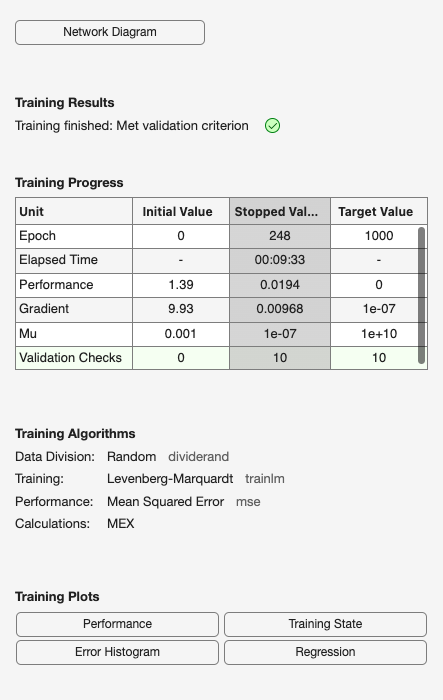


% Normalize Input
mu = mean(XY_all);
sigma = std(XY_all);
X_norm = (XY_all - mu) ./ sigma;

% Split Train/Test
N = size(X_norm, 1);
idx = randperm(N);
split = round(0.9 * N);

X_train = X_norm(idx(1:split), :)';
Y_train = heading_all(idx(1:split), :)';

X_test  = X_norm(idx(split+1:end), :)';
Y_test  = heading_all(idx(split+1:end), :)';

% Train Neural Network
net = feedforwardnet(hiddenLayers);
net = configure(net, X_train, Y_train);
net.trainParam.showWindow = true;
net.trainParam.epochs = 1000;
net.trainParam.max_fail = 10;

[net, tr] = train(net, X_train, Y_train);

## Save the Neural Network Model Parameters

%% === Save Model ===
NNMagCal.net = net;
NNMagCal.mu  = mu;
NNMagCal.sigma = sigma;
save('NNMagCal_2D.mat', 'NNMagCal');  % Save all in one .mat file

## Compute cosine simularity and average deviation

% Compute cosine similarity safely
Y_pred = net(X_test);
dot_product = sum(Y_pred .* Y_test, 1);          % 1xN
norm_pred   = vecnorm(Y_pred, 2, 1);             % 1xN
norm_true   = vecnorm(Y_test, 2, 1);             % 1xN

% Prevent divide-by-zero
valid = (norm_pred > 1e-6) & (norm_true > 1e-6);
cos_sim = NaN(size(dot_product));
cos_sim(valid) = dot_product(valid) ./ (norm_pred(valid) .* norm_true(valid));

% Mean over valid entries
mean_cos_sim = mean(cos_sim(valid));
fprintf("Mean cosine similarity (test set): %.4f rad\n", mean_cos_sim);

Mean cosine similarity (test set): 0.9783 rad


fprintf("Prediction's average deviation from the GT: %.4f°\n", rad2deg(acos(mean_cos_sim)));

Prediction's average deviation from the GT: 11.9593°


## Prepare the function for applying the calibration

function [yaw_est, heading_vec] = applyNNMagnetometerCalibration2D(XY_raw, modelPath)
% Applies trained NN magnetometer calibration to new data
%
% Inputs:
%   XY_raw   - Nx2 matrix of raw magnetometer readings [Mx, My]
%   modelPath - Path to saved .mat model file (e.g. 'NNMagCal_2D.mat')
%
% Outputs:
%   yaw_est     - Nx1 vector of predicted yaw (radians)
%   heading_vec - Nx2 normalized heading vectors [cos(yaw), sin(yaw)]

    % Load the trained model and normalization parameters
    data = load(modelPath, 'NNMagCal');
    net   = data.NNMagCal.net;
    mu    = data.NNMagCal.mu;
    sigma = data.NNMagCal.sigma;

    % Normalize input
    X_norm = (XY_raw - mu) ./ sigma;

    % Predict heading vectors
    heading_vec = net(X_norm')';  % Output Nx2

    % Convert to yaw angle
    yaw_est = unwrap(atan2(heading_vec(:,2), heading_vec(:,1)));
end

## Testing on a different data set, Visualization and Evaluation

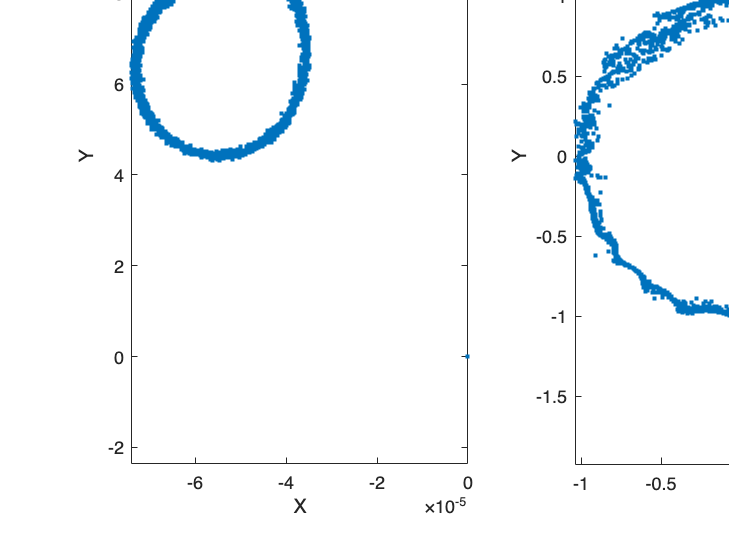

line = load("../trainingData/calib1_rotate.mat");

% GT data
GT_position = squeeze(line.out.GT_position.signals.values);
GT_rotation = squeeze(line.out.GT_rotation.signals.values);
GT_time = squeeze(line.out.GT_position.time);

% Magnitometer Data
Mraw = squeeze(line.out.Sensor_MAG.signals.values)';
M_time = squeeze(line.out.Sensor_MAG.time)';
Mx   = Mraw(:,2);
My   = Mraw(:,3);

% Combine for 2D
XY_raw = [Mx, My];

[yaw_est, heading_vec] = applyNNMagnetometerCalibration2D(XY_raw, "NNMagCal_2D.mat");

figure;
% Subplot 1: Uncalibrated magnetometer data
subplot(1,2,1);
plot(Mraw(:,2), Mraw(:,3), '.');
title('Uncalibrated Magnetometer');
xlabel('X'); ylabel('Y');
axis equal;

% Subplot 2: Calibrated heading vector
subplot(1,2,2);
plot(heading_vec(:,1), heading_vec(:,2), '.');
title('Calibrated Data');
xlabel('X'); ylabel('Y');
axis equal;
exportgraphics(gcf, 'magcal_heading.png');



yaw_gt = quat2eul(GT_rotation, 'ZXY');  % [yaw, pitch, roll]
yaw_gt = yaw_gt(:,1);                   % Take yaw only (in radians)
yaw_gt = unwrap(yaw_gt);    % Unwrap to prevent jumps at ±π

figure;
plot(GT_time, rad2deg(yaw_gt), 'k', 'LineWidth', 1.5); hold on;
plot(M_time, rad2deg(yaw_est), 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Yaw (degrees)');
legend('Ground Truth Yaw', 'Magnetometer (Tilt-Corrected)');
title('Yaw Angle Comparison');
grid on;
exportgraphics(gcf, 'magcal_yaw.png');

### Print Metrics

yaw_error = wrapToPi(yaw_est - yaw_gt);
yaw_rmse = sqrt(mean(yaw_error.^2));
fprintf("RMSE after frame alignment: %.2f°\n", rad2deg(yaw_rmse));

RMSE after frame alignment: 16.14°


## Visualise the heading 

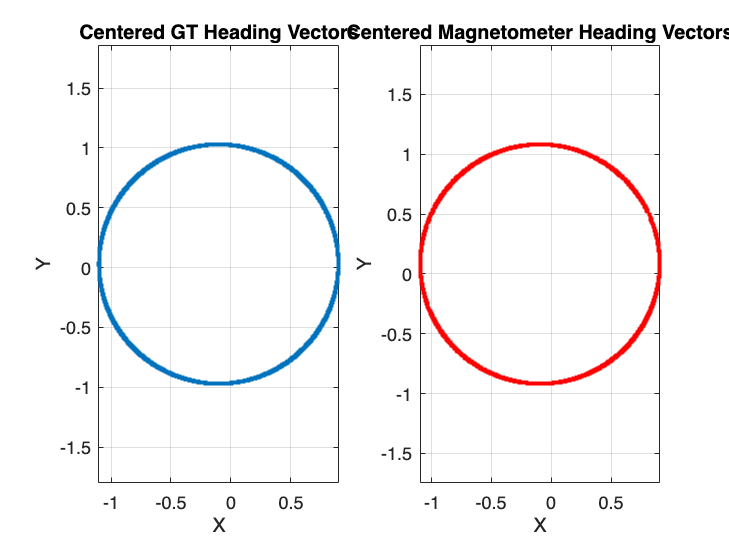

% Represent both as 2D heading vectors
v_gt = [cos(yaw_gt), sin(yaw_gt)];
v_mag = [cos(yaw_est), sin(yaw_est)];

% Center vectors
v_gt_centered = v_gt - mean(v_gt, 1);
v_mag_centered = v_mag - mean(v_mag, 1);

figure;
subplot(1,2,1);
plot(v_gt_centered(:,1), v_gt_centered(:,2), '.', 'DisplayName', 'GT');
axis equal; grid on;
xlabel('X'); ylabel('Y');
title('Centered GT Heading Vectors');

subplot(1,2,2);
plot(v_mag_centered(:,1), v_mag_centered(:,2), 'r.', 'DisplayName', 'Mag');
axis equal; grid on;
xlabel('X'); ylabel('Y');
title('Centered Magnetometer Heading Vectors');